clc;close all;clear 

%Cargar archivos
g21 = load('C:\Users\crisa\OneDrive\Escritorio\GitHub\Dinamica-de-estructuras\Datos y código\g21.txt'); %Desplazamiento incial conocido
g22 = load('C:\Users\crisa\OneDrive\Escritorio\GitHub\Dinamica-de-estructuras\Datos y código\g22.txt'); %Golpe
g23 = load('C:\Users\crisa\OneDrive\Escritorio\GitHub\Dinamica-de-estructuras\Datos y código\g23.txt'); %Estructura con amortiguamiento
g24 = load('C:\Users\crisa\OneDrive\Escritorio\GitHub\Dinamica-de-estructuras\Datos y código\g24.txt'); %Resonancia 

%Constantes sensores
c_estructura = 1.029; 
c_forzante = 1.028;

%Vectores de tiempo de cada registro
t1 = g21(:,1);
t2 = g22(:,1);
t3 = g23(:,1);
t4 = g24(:,1);

%Respuesta aceleración sistema [g]
Respuesta_1 = g21(:,2)./c_estructura;
Respuesta_2 = g22(:,2)./c_estructura;
Respuesta_3 = g23(:,2)./c_estructura;
Respuesta_4 = g24(:,2)./c_estructura;

%Datos de la forzante [g]
Respuesta_for_1 = g21(:,3)./c_forzante;
Respuesta_for_2 = g22(:,3)./c_forzante;
Respuesta_for_3 = g23(:,3)./c_forzante;
Respuesta_for_4 = g24(:,3)./c_forzante;

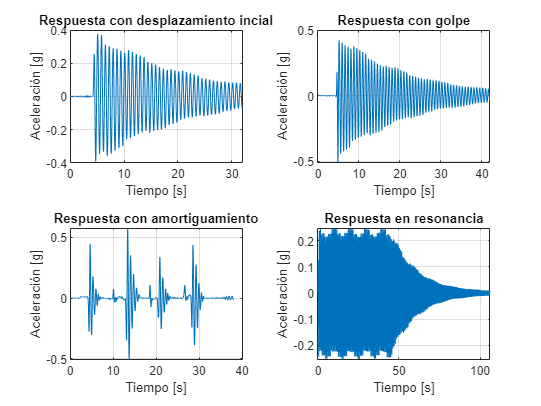

%Gráfico respuestas aceleración
figure()
nexttile
plot(t1,Respuesta_1)
xlabel('Tiempo [s]')
ylabel('Aceleración [g]')
title('Respuesta con desplazamiento incial')
grid
nexttile
plot(t2,Respuesta_2)
xlabel('Tiempo [s]')
ylabel('Aceleración [g]')
title('Respuesta con golpe')
grid
nexttile
plot(t3,Respuesta_3)
xlabel('Tiempo [s]')
ylabel('Aceleración [g]')
title('Respuesta con amortiguamiento')
grid
nexttile
plot(t4,Respuesta_4)
xlabel('Tiempo [s]')
ylabel('Aceleración [g]')
title('Respuesta en resonancia')
grid

%Recortamos el vector de datos para calcular frecuencias naturales
Resp1_rec = Respuesta_1(2001:6001); %Desplazamiento inicial conocido
Resp2_rec = Respuesta_2(2001:6001); %Golpe
Resp3_rec = Respuesta_3(2543:3239); %Amortiguamiento
Resp4_rec = Respuesta_4(10001:20001); %Disipación forzante
Resp5_rec = Respuesta_4(2001:8001); %Resonacia

%Recortamos tiempos
t1_rec = t1(2001:6001);
t2_rec = t2(2001:6001);
t3_rec = t3(2543:3239);
t4_rec = t4(10001:20001);
t5_rec = t4(2001:8001);

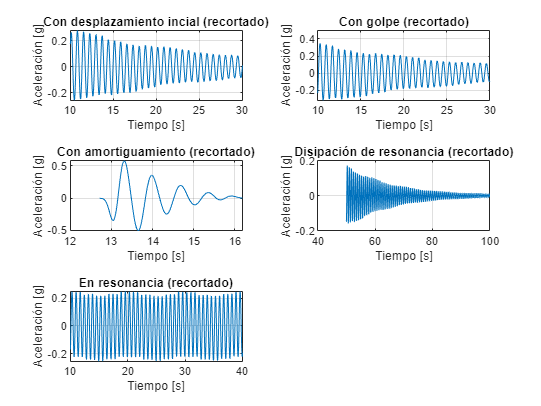

%Gráfico respuestas aceleración recortadas
figure()
nexttile
plot(t1_rec,Resp1_rec)
xlabel('Tiempo [s]')
ylabel('Aceleración [g]')
title('Con desplazamiento incial (recortado)')
grid
nexttile
plot(t2_rec,Resp2_rec)
xlabel('Tiempo [s]')
ylabel('Aceleración [g]')
title('Con golpe (recortado)')
grid
nexttile
plot(t3_rec,Resp3_rec)
xlabel('Tiempo [s]')
ylabel('Aceleración [g]')
title('Con amortiguamiento (recortado)')
grid
nexttile
plot(t4_rec,Resp4_rec)
xlabel('Tiempo [s]')
ylabel('Aceleración [g]')
title('Disipación de resonancia (recortado)')
grid
nexttile
plot(t5_rec,Resp5_rec)
xlabel('Tiempo [s]')
ylabel('Aceleración [g]')
title('En resonancia (recortado)')
grid

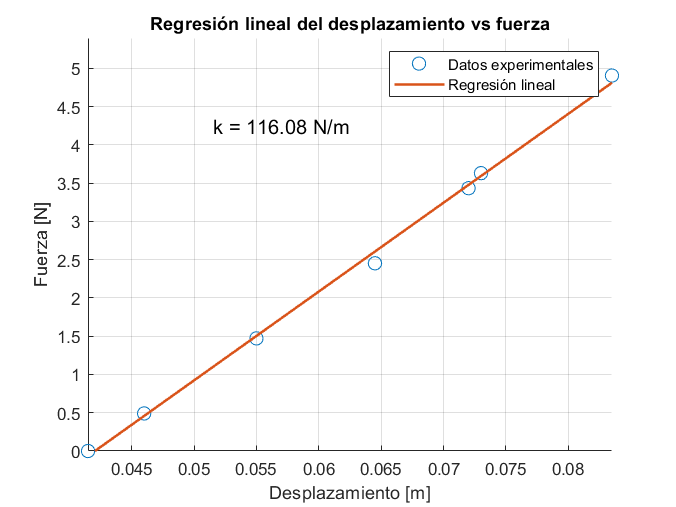

% Convertir longitudes a metros y fuerzas a Newtons
l = [4.15 4.6 5.5 6.45 7.2 7.3 8.35] / 100; %[m]
p = [0 50 150 250 350 370 500] * 9.81e-3; %[N]

% Regresión lineal
coefficients = polyfit(l, p, 1); 
k = coefficients(1); % [N/m]

M = 0.635; %[kg]

% Periodo teórico
w = sqrt(k/M); % [rad/s]
T = (2*pi)/(w); % [s]

% Valores de la regresión para el gráfico
l_fit = linspace(min(l), max(l), 100); % Puntos para la línea de regresión
p_fit = polyval(coefficients, l_fit); % Evaluar la regresión lineal

% Crear el gráfico
figure;
hold on;
plot(l, p, 'o', 'MarkerSize', 8, 'DisplayName', 'Datos experimentales'); % Datos experimentales
plot(l_fit, p_fit, '-', 'LineWidth', 1.5, 'DisplayName', 'Regresión lineal'); % Línea de regresión
xlabel('Desplazamiento [m]');
ylabel('Fuerza [N]');
grid on;
title('Regresión lineal del desplazamiento vs fuerza');
x_pos = min(l) + 0.01; 
y_pos = max(p) * 0.9; 
text(x_pos, y_pos, ['k = ' num2str(k, '%.2f') ' N/m'], 'FontSize', 12, 'Color', 'k', 'VerticalAlignment', 'top');
xlim([min(l) max(l)]);
ylim([0 max(p) * 1.1]); 

legend('show');
hold off;

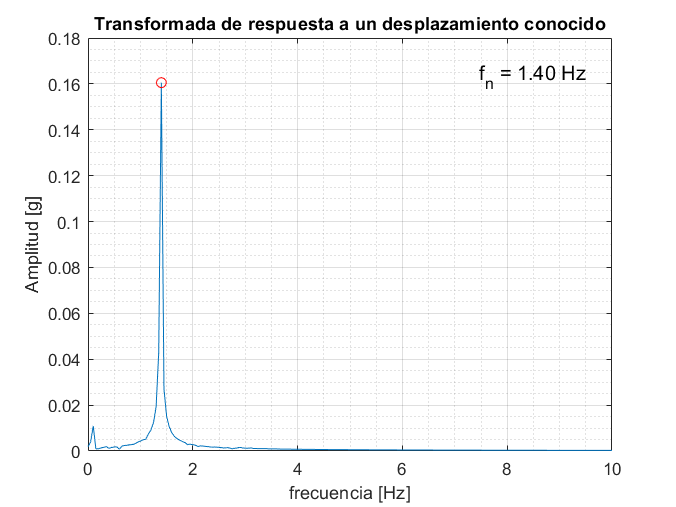

%TRANSFORMADAS DE FOURIER

%Calculo de periodo
Fs = 200;

% ---- Transformada de Fourier desplazamiento inicial ----
TF_g11 = fft(Resp1_rec);
L1 = length(Resp1_rec);
P2_g11 = abs(TF_g11/L1);
P1_g11 = P2_g11(1:floor(L1/2)+1);
P1_g11(2:end-1) = 2*P1_g11(2:end-1);
f_g11 = Fs*(0:(L1/2))/L1;
figure()
plot(f_g11,P1_g11)
hold on
grid
grid minor
xlabel('frecuencia [Hz]')
xlim([0 10])
ylabel('Amplitud [g]')
title('Transformada de respuesta a un desplazamiento conocido')
Max_P1_g11 = max(P1_g11);
indice_Max_P1_g11 = find(P1_g11 == Max_P1_g11);
f1 = f_g11(indice_Max_P1_g11);
plot(f1, Max_P1_g11, 'ro') % Marcamos el máximo en rojo

% Mostrar frecuencia natural
text(0.95, 0.95, ['f_n = ' num2str(f1, '%.2f') ' Hz'], 'Units', 'normalized', ...
     'VerticalAlignment', 'top', 'HorizontalAlignment', 'right', 'FontSize', 12)
hold off

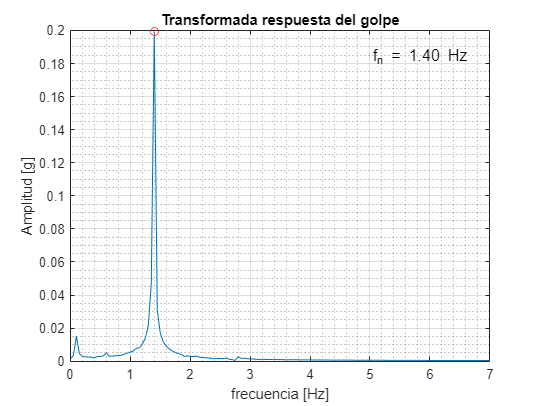


% ---- Transformada de Fourier respuesta del golpe ----
TF_g12 = fft(Resp2_rec);
L2 = length(Resp2_rec);
P2_g12 = abs(TF_g12/L2);
P1_g12 = P2_g12(1:floor(L2/2)+1);
P1_g12(2:end-1) = 2*P1_g12(2:end-1);
f_g12 = Fs*(0:(L2/2))/L2;
figure()
plot(f_g12,P1_g12)
hold on
grid
grid minor
xlabel('frecuencia [Hz]')
xlim([0 7])
ylabel('Amplitud [g]')
title('Transformada respuesta del golpe')
Max_P1_g12 = max(P1_g12);
indice_Max_P1_g12 = find(P1_g12 == Max_P1_g12);
f2 = f_g12(indice_Max_P1_g12);
plot(f2, Max_P1_g12, 'ro') % Marcamos el máximo en rojo

% Mostrar frecuencia natural
text(0.95, 0.95, ['f_n = ' num2str(f2, '%.2f') ' Hz'], 'Units', 'normalized', ...
     'VerticalAlignment', 'top', 'HorizontalAlignment', 'right', 'FontSize', 12)
hold off

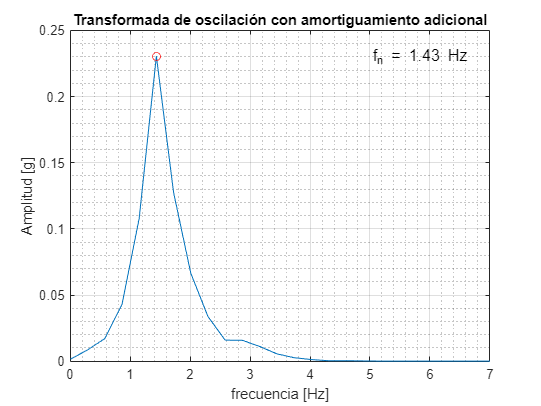


% ---- Transformada de Fourier oscilación amortiguada ----
TF_g13 = fft(Resp3_rec);
L3 = length(Resp3_rec);
P2_g13 = abs(TF_g13/L3);
P1_g13 = P2_g13(1:floor(L3/2)+1);
P1_g13(2:end-1) = 2*P1_g13(2:end-1);
f_g13 = Fs*(0:(L3/2))/L3;
figure()
plot(f_g13,P1_g13)
hold on
grid
grid minor
xlabel('frecuencia [Hz]')
xlim([0 7])
ylabel('Amplitud [g]')
title('Transformada de oscilación con amortiguamiento adicional')
Max_P1_g13 = max(P1_g13);
indice_Max_P1_g13 = find(P1_g13 == Max_P1_g13);
f3 = f_g13(indice_Max_P1_g13);
plot(f3, Max_P1_g13, 'ro') % Marcamos el máximo en rojo

% Mostrar frecuencia natural
text(0.95, 0.95, ['f_n = ' num2str(f3, '%.2f') ' Hz'], 'Units', 'normalized', ...
     'VerticalAlignment', 'top', 'HorizontalAlignment', 'right', 'FontSize', 12)
hold off

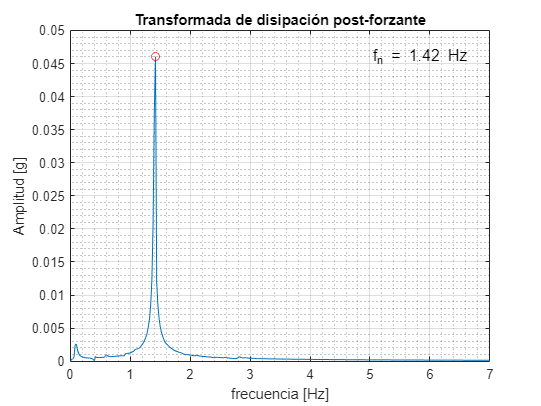


% ---- Transformada de Fourier disipación post-resonancia ----
TF_g14 = fft(Resp4_rec);
L4 = length(Resp4_rec);
P2_g14 = abs(TF_g14/L4);
P1_g14 = P2_g14(1:floor(L4/2)+1);
P1_g14(2:end-1) = 2*P1_g14(2:end-1);
f_g14 = Fs*(0:(L4/2))/L4;
figure()
plot(f_g14,P1_g14)
hold on
grid
grid minor
xlabel('frecuencia [Hz]')
xlim([0 7])
ylabel('Amplitud [g]')
title('Transformada de disipación post-forzante')
Max_P1_g14 = max(P1_g14);
indice_Max_P1_g14 = find(P1_g14 == Max_P1_g14);
f4 = f_g14(indice_Max_P1_g14);
plot(f4, Max_P1_g14, 'ro') % Marcamos el máximo en rojo

% Mostrar frecuencia natural
text(0.95, 0.95, ['f_n = ' num2str(f4, '%.2f') ' Hz'], 'Units', 'normalized', ...
     'VerticalAlignment', 'top', 'HorizontalAlignment', 'right', 'FontSize', 12)
hold off

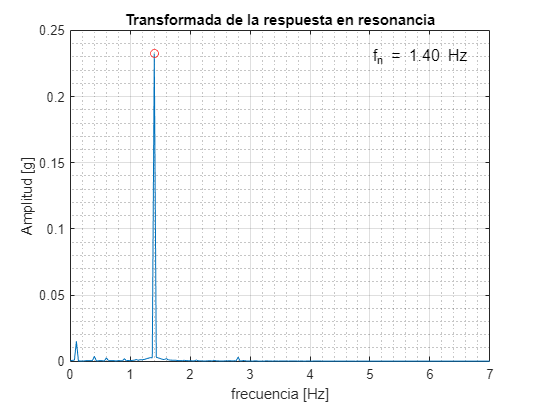


% ---- Transformada de Fourier respuesta en resonancia ----
TF_g15 = fft(Resp5_rec);
L5 = length(Resp5_rec);
P2_g15 = abs(TF_g15/L5);
P1_g15 = P2_g15(1:floor(L5/2)+1);
P1_g15(2:end-1) = 2*P1_g15(2:end-1);
f_g15 = Fs*(0:(L5/2))/L5;
figure()
plot(f_g15,P1_g15)
hold on
grid
grid minor
xlabel('frecuencia [Hz]')
xlim([0 7])
ylabel('Amplitud [g]')
title('Transformada de la respuesta en resonancia')
Max_P1_g15 = max(P1_g15);
indice_Max_P1_g15 = find(P1_g15 == Max_P1_g15);
f5 = f_g15(indice_Max_P1_g15);
plot(f5, Max_P1_g15, 'ro') % Marcamos el máximo en rojo

% Mostrar frecuencia natural
text(0.95, 0.95, ['f_n = ' num2str(f5, '%.2f') ' Hz'], 'Units', 'normalized', ...
     'VerticalAlignment', 'top', 'HorizontalAlignment', 'right', 'FontSize', 12)
hold off

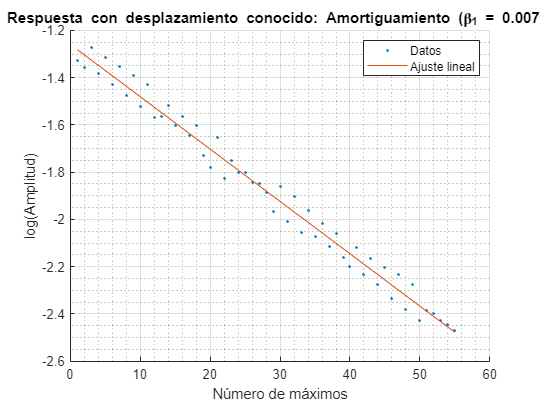

% Calculo de beta

% Para la respuesta 1
A_1_abs = abs(Resp1_rec);   
peaks_A1 = findpeaks(A_1_abs); % Encuentra picos
num_maximos1 = linspace(1, length(peaks_A1), length(peaks_A1)); % Número de máximos

% Para la respuesta 2
A_2_abs = abs(Resp2_rec);
peaks_A2 = findpeaks(A_2_abs);
num_maximos2 = linspace(1, length(peaks_A2), length(peaks_A2));

% Para la respuesta 3
A_3_abs = abs(Resp3_rec);
peaks_A3 = findpeaks(A_3_abs);
num_maximos3 = linspace(1, length(peaks_A3), length(peaks_A3));

% Para la respuesta 4
A_4_abs = abs(Resp4_rec);
peaks_A4 = findpeaks(A_4_abs);
num_maximos4 = linspace(1, length(peaks_A4), length(peaks_A4));

% Regresiones lineales en el espacio logarítmico
regresion1 = polyfit(num_maximos1, log(peaks_A1), 1); 
beta1 = abs(regresion1(1))/pi;

regresion2 = polyfit(num_maximos2, log(peaks_A2), 1); 
beta2 = abs(regresion2(1))/pi;

regresion3 = polyfit(num_maximos3, log(peaks_A3), 1); 
beta3 = abs(regresion3(1))/pi;

regresion4 = polyfit(num_maximos4, log(peaks_A4), 1); 
beta4 = abs(regresion4(1))/pi;

% Valores de las líneas de ajuste
reg1 = regresion1(1).*num_maximos1 + regresion1(2);
reg2 = regresion2(1).*num_maximos2 + regresion2(2);
reg3 = regresion3(1).*num_maximos3 + regresion3(2);
reg4 = regresion4(1).*num_maximos4 + regresion4(2);

% Graficar respuesta desplazamiento conocido
figure()
hold on
plot(num_maximos1, log(peaks_A1), '.', 'DisplayName', 'Datos')
plot(num_maximos1, reg1, '-', 'DisplayName', 'Ajuste lineal')
xlabel('Número de máximos')
ylabel('log(Amplitud)')
title(['Respuesta con desplazamiento conocido: Amortiguamiento (\beta_1 = ', num2str(beta1, '%.4f'), ')'])
legend()
grid on
grid minor
hold off

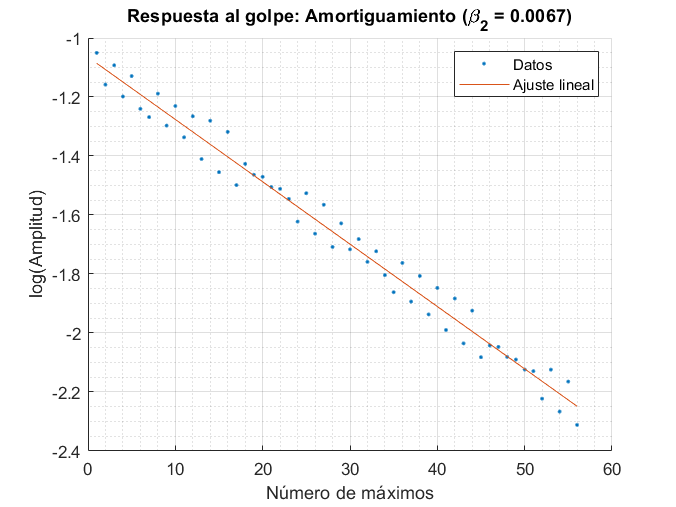


% Graficar respuesta del golpe
figure()
hold on
plot(num_maximos2, log(peaks_A2), '.', 'DisplayName', 'Datos')
plot(num_maximos2, reg2, '-', 'DisplayName', 'Ajuste lineal')
xlabel('Número de máximos')
ylabel('log(Amplitud)')
title(['Respuesta al golpe: Amortiguamiento (\beta_2 = ', num2str(beta2, '%.4f'), ')'])
legend()
grid on
grid minor
hold off

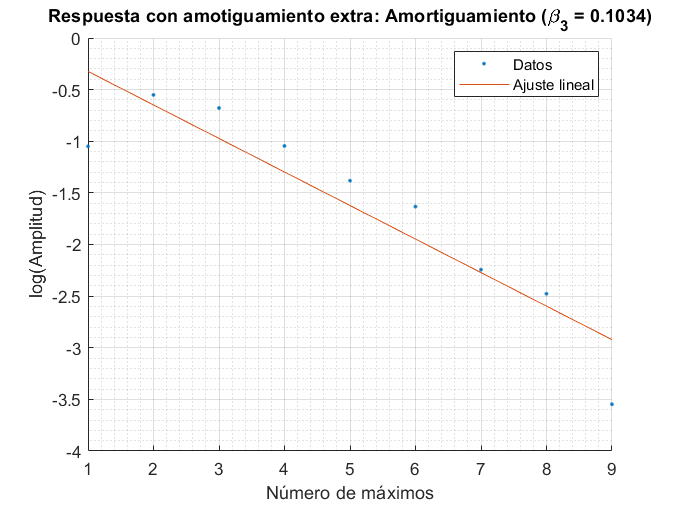


% Graficar respuesta oscilación amortiguada
figure()
hold on
plot(num_maximos3, log(peaks_A3), '.', 'DisplayName', 'Datos')
plot(num_maximos3, reg3, '-', 'DisplayName', 'Ajuste lineal')
xlabel('Número de máximos')
ylabel('log(Amplitud)')
title(['Respuesta con amotiguamiento extra: Amortiguamiento (\beta_3 = ', num2str(beta3, '%.4f'), ')'])
legend()
grid on
grid minor
hold off

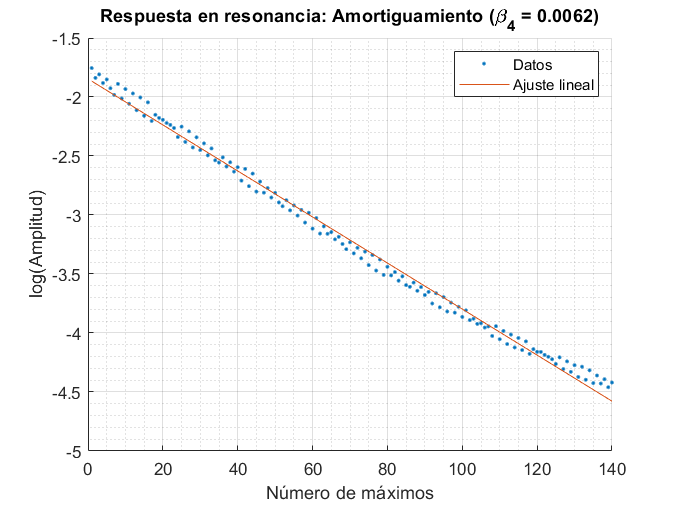


% Graficar respuesta en resonancia
figure()
hold on
plot(num_maximos4, log(peaks_A4), '.', 'DisplayName', 'Datos')
plot(num_maximos4, reg4, '-', 'DisplayName', 'Ajuste lineal')
xlabel('Número de máximos')
ylabel('log(Amplitud)')
title(['Respuesta en resonancia: Amortiguamiento (\beta_4 = ', num2str(beta4, '%.4f'), ')'])
legend()
grid on
grid minor
hold off

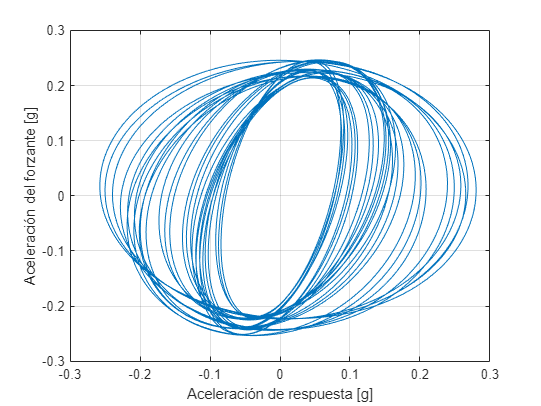

%Aceleración forzante vs aceleración de la respuesta
Resp_forz_rec = Respuesta_4(2001:6001);
figure
plot(Resp1_rec,Resp_forz_rec)
xlabel('Aceleración de respuesta [g]')
ylabel('Aceleración del forzante [g]')
grid


vo = peaks_A2(1)/(mean([f1,f2,f3,f4])*2*pi); %Velocidad inicial

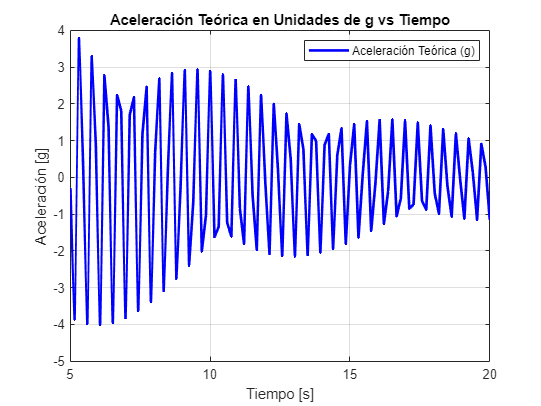

%Respuesta teórica v/s respuesta experimental. Se compará la respuesta con desplazamiento inicial conocido.

%Datos
beta = (beta1+beta2+beta4)/3;
K = k; %116.0832 [N/m]
m = M; %0.635 [kg]
x_0 = 38.5/100; %[m] (velocidad inicial=0)
w_n = sqrt(K/m);%[Hz]
w_d = w_n*sqrt(1-beta^2);

%Tiempo a considerar
t = linspace(5, 20, 100);

%Solución teórica
A=beta*w_n*x_0/w_d;
B=x_0;
A_1 = -A*beta*w_n-B*w_d;
B_1 = A*w_d-B*beta*w_n;
A_2 = -A_1*beta*w_n-B_1*w_d;
B_2 = A_1*w_d-B_1*beta*w_n;
x_teo = exp(-beta*w_n*t).*(A*sin(w_d*t) + B*cos(w_d*t));%No se usará pero igual lo tendremos
v_teo = exp(-beta*w_n*t).*(A_1*sin(w_d*t)+B_1*cos(w_d*t));%Tampoco se usará
a_teo = exp(-beta*w_n*t).*(A_2*sin(w_d*t)+B_2*cos(w_d*t));%Este sí
a_teo_g = a_teo/9.81; %Aceleración en unidades de g

% Gráfico de la aceleración en unidades de g
figure;
plot(t, a_teo_g, 'b-', 'LineWidth', 2); % Gráfico de a_teo en g
xlabel('Tiempo [s]');
ylabel('Aceleración [g]');
title('Aceleración Teórica en Unidades de g vs Tiempo');
grid on;
legend('Aceleración Teórica (g)');